Read time, right wheel angular velocity, and left wheel angular velocity from 'stepsim_data.mat' (generated by 'ReadFromArduino.mlx'.

Use the values from 'stepsim_data.mat' to calculate position and orientation.

% retrieve 'data' from 'stepData.mat'
load('stepData.mat');

% sampling time (100 ms)
delta_t = 0.1

delta_t = 0.1000

% radius of wheels
radius = 0.07;
% distance between wheels
baseline = 0.28;
% number of rows in 'data'
num_rows = height(data);
% initial position/orientation of robot
x_pos = 0;
y_pos = 0;
orientation = 0;
% generate matrices
sim_data = zeros(num_rows, 4);
velocity_data = zeros(num_rows, 3);
% copy time (first column) from 'data' to the first column of 'sim_data'
sim_data(:,1) = data(:,1);

% calculate left/right wheel linear velocities
for i = (1:num_rows) % for each entry in given column
    % store right wheel linear velocity in first column of 'velocity_data'
    velocity_data(i,1) = radius * data(i,2);
    % store left wheel linear velocity in second column of 'velocity_data'
    velocity_data(i,2) = radius * data(i,3);
end

% calculate reorientation velocities
for i = (1:num_rows) % for each entry in given column
    % store reorientation velocities in third column of 'velocity_data'
    velocity_data(i,3) = (velocity_data(i,1) - velocity_data(i,2)) / baseline;
end

% calculate orientations (phi)
for i = (1:num_rows) % for each entry in given column
    % update orientation based on reorientation velocity
    orientation = orientation + (delta_t * velocity_data(i,3));
    % store given orientation in fourth column of 'sim_data'
    sim_data(i,4) = orientation;
end

% calculate x and y positions
for i = (1:num_rows) % for each entry in given column
    % update/store x position in second column of 'sim_data'
    x_pos =  x_pos + delta_t*cos(sim_data(i,4))*(velocity_data(i,1)+velocity_data(i,2)) / 2;
    sim_data(i,2) = x_pos;
    % update/store y position in third column of 'sim_data'
    y_pos =  y_pos + delta_t*sin(sim_data(i,4))*(velocity_data(i,1)+velocity_data(i,2)) / 2;
    sim_data(i,3) = y_pos;
end

% store elapsed time in first column of 'sim_data'
for i = (1:num_rows) % for each entry in given column
    sim_data(i,1) = data(i,1);
end


Time, x-position, y-position, and orientation are in columns 1, 2, 3, and 4 respectively.

% also DO NOT TOUCH
time = sim_data(:,1);
xposition = sim_data(:,2);
yposition = sim_data(:,3);
phi = sim_data(:,4);

The rest is done for us: DO NOT TOUCH.

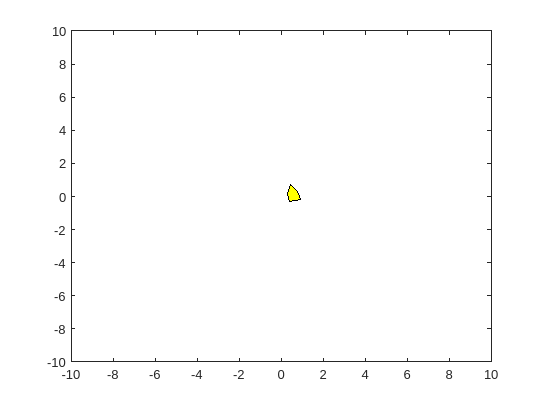

% Define shape verticies
% first row is x position, second row is y position

r_width = .5;
r_length = 1;
V = [-r_length/2 -r_length/2 0         r_length/2    0;
     -r_width/2   r_width/2  r_width/2 0            -r_width/2];

figure
for i=1:length(time),
    % move shape by moving verticies
    % define rotation matrix
    T = [cos(phi(i)) -sin(phi(i));sin(phi(i)) cos(phi(i))];
    % define center position
    pos = [xposition(i);yposition(i)];
    % find position of current vertices: each position is multiplied by the rotation
    %matrix, and added to the current position
    v_c = T*V+pos*ones(1,5);
    % draw shape
    fill(v_c(1,:),v_c(2,:),'y')
    axis([-10 10 -10 10]) % set axis to have specified x and y limits
    % (type 'help axis' for more info)
    % make sure matlab draws the figure now
    drawnow
    % if not last drawing, wait
    if i<length(time),
    pause((time(i+1)-time(i)) / 1000)
    end;
end;